   files = ["./pca_fixed/fixedata.ply", "./busako_printed_scan/busako_printed_scan025_2ROT.stl", ...
    "./stl/Busako_printed_scan025_fix.stl", "./pca_fixed/Nov15_pcafix.ply", ...
    "./stl/busako_naname_reScale.stl"];

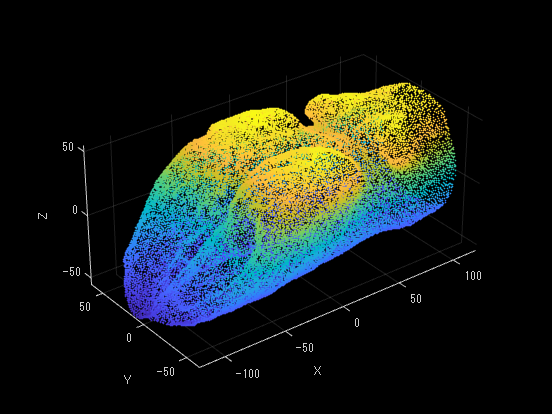

% filename = uigetfile({'*.stl';'*.ply'});
filename = files(3);
if contains(filename, 'stl')
    mesh = stlread(filename);
    scale = 1000;
    pt = (mesh.Points).*scale;
%     pt = mesh.Points;
    sPoint = pointCloud(pt);
elseif contains(filename, 'ply')
    sPoint = pcread(filename);
else
    disp('Not Found');
end
pcshowWithAxes(sPoint);

cutWidthT = 0.5;
axesString = ["x","y","z"];
axes = axesString(1);

一度周囲長と断面積を計算

originalData= CalculateCircum(sPoint, axes, cutWidthT);

点群が足りないよ


x = originalData(:,1);
area = originalData(:,3);

もし蹄が負の方向を向いていたら、正の方向へ反転させる

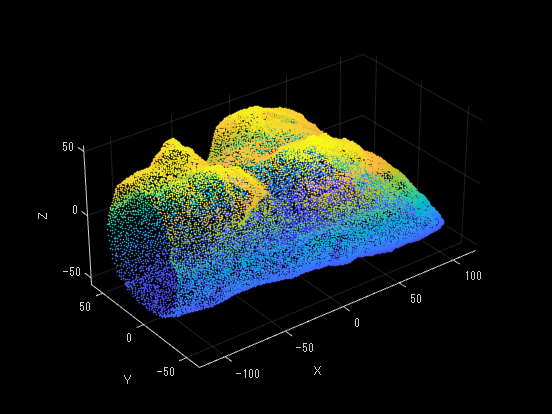

[~, I] = max(area);
rotAxes = axesString(3);
if x(I) < 0
    sPoint = rotatePoint(sPoint, pi, rotAxes);
    pcshowWithAxes(sPoint);
end

新しいデータ上で解析

CircumData= CalculateCircum(sPoint, axes, cutWidthT);

点群が足りないよ


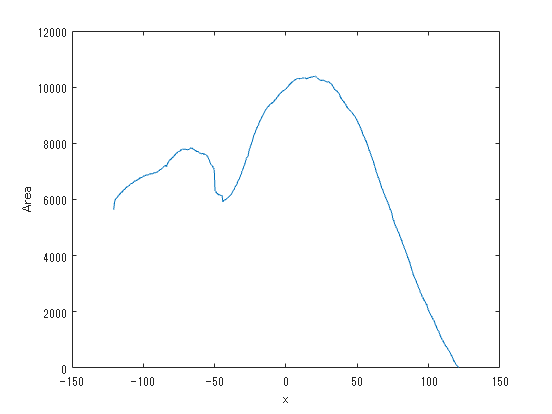

x = CircumData(:,1);
area = CircumData(:,3);
[areaMax, I] = max(area);
figure('Name','firstPlot')
plot(x,area);
xlabel('x');ylabel('Area');

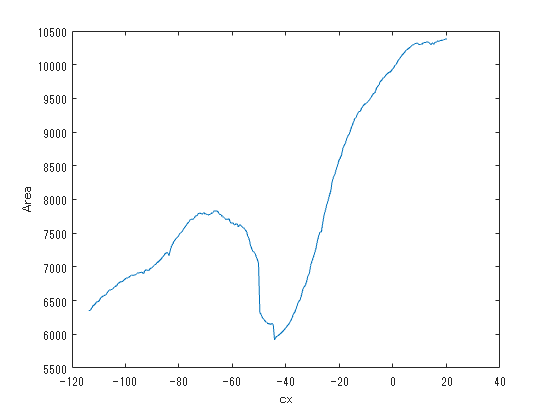

cutData = CircumData(CircumData(:,1) > x(I)-135 & x(I) > CircumData(:,1), :);
cx  = cutData(:,1);
cArea = cutData(:,3);
figure('Name', 'Cut at AreaMax');
plot(cx, cArea);
xlabel('cx');ylabel('Area');

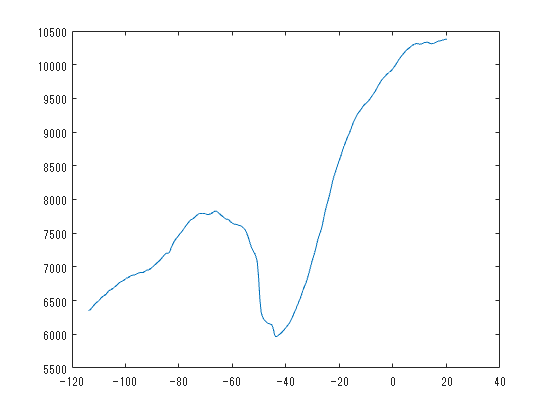


n = 1;
Wn = 0.4;
[y1, v1, v2] = filterAnddiff(cArea, n, Wn);
figure('Name','Filtering');
plot(cx,y1);

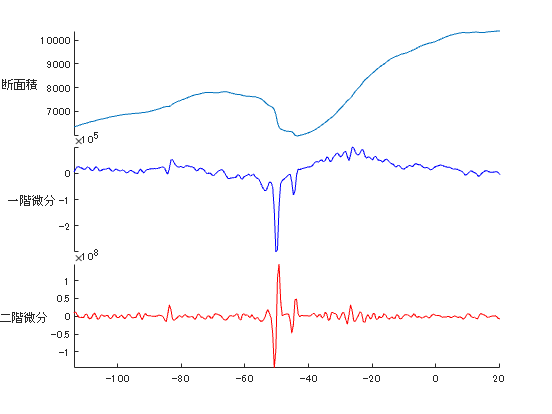

figure;
newLabels = ["断面積", "一階微分", "二階微分"];
s = stackedplot(cx, [y1, v1, v2], 'DisplayLabels',newLabels, 'Color','r');
s.LineProperties(1).Color = '#0072BD';
s.LineProperties(2).Color = 'b';
s.LineProperties(3).Color = 'r';

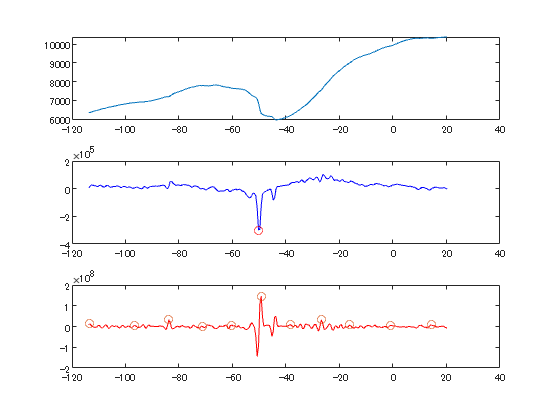

TF = islocalmin(v1, 'MaxNumExtrema',1 );

[pkv2, locv2] = findpeaks(v2, cx, 'MinPeakDistance',10, 'Annotate','extents');

figure('Name', 'subplot');
subplot(3, 1,1);
plot(cx, y1);
subplot(3,1,2);
% plot(cx,v1,'b',locv1,pkv1, 'o');
plot(cx,v1,'b',cx(TF),v1(TF), 'ro');
subplot(3, 1, 3);
plot(cx, v2,'r',locv2, pkv2, 'o');

% 一階微分の局所最小値以下の解析
recutData = cutData(cutData(:,1) < cx(TF)-10, :);
rx = recutData(:,1);
rArea = recutData(:,3);

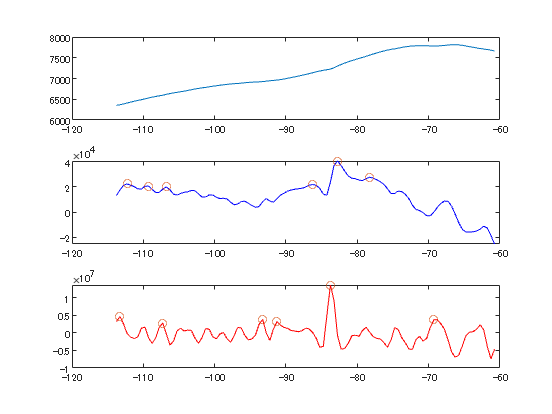

n = 2;
Wn = 0.3;
[yr, v1_r, v2_r] = filterAnddiff(rArea);


[pkv1_r, locv1_r, width1, proms1] = findpeaks(v1_r, rx, 'MinPeakHeight',20000);
[pkv2_r, locv2_r, wudth2, proms2] = findpeaks(v2_r, rx, 'MinPeakHeight',2500000);

figure('Name', 'Second Range Search');
subplot(3,1,1);
plot(rx, yr);
subplot(3,1,2);
plot(rx,v1_r,'b', locv1_r, pkv1_r,'o');
subplot(3,1,3)

plot(rx, v2_r, 'r', locv2_r, pkv2_r, 'o');

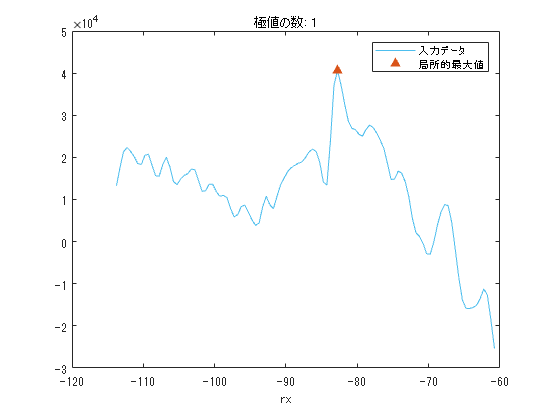

% 局所的最大値の検出
maxIndices = islocalmax(v1_r,"MinProminence",20000,"SamplePoints",rx);

% 結果の表示
figure
plot(rx,v1_r,"Color",[77 190 238]/255,"DisplayName","入力データ")
hold on

% 局所的最大値のプロット
plot(rx(maxIndices),v1_r(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","局所的最大値")
title("極値の数: " + nnz(maxIndices))
hold off
legend
xlabel("rx")

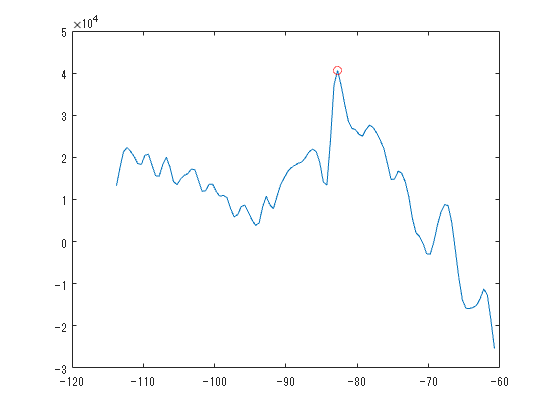

mTF = islocalmax(v1_r, 'MinProminence',20000);
plot(rx, v1_r, rx(mTF), v1_r(mTF), 'ro');

localMaxSet = [rx(mTF) v1_r(mTF)];
disp(localMaxSet);

   1.0e+04 *

  -0.008277206474543   4.062029461788825



[maxPoint, I] = max(localMaxSet(:,2));
rx_extream = localMaxSet(I);
disp(localMaxSet(I,2));

     4.062029461788825e+04




samplingWidth = 4;
% samplemin = rx(mTF)-samplingWidth;
% samplemax = rx(mTF);
samplemin = rx_extream-samplingWidth;
samplemax = rx_extream;
sampleData = recutData(recutData(:,1) > samplemin & samplemax > recutData(:,1),:);

Circum = mean(sampleData(:,2));
fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin, samplemax, Circum);

-86.772065 < dt < -82.772065の時, 平均周囲長は 300.657529 


pcshowWithAxes(sPoint, 'marking');
hold on;
sP = sPoint.Location;
idx = 1

idx =      1


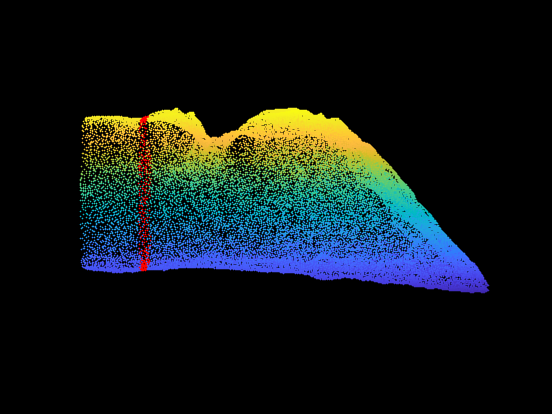

samplePoint = sP(sP(:,idx) > samplemin & sP(:,idx) < samplemax, :);
pcshow(samplePoint,'r');
hold off;